## NASA Turbofan Level B2: Understand your data and your modelling goal

clc; close all; clear all; 

### Data loading and standardization

% Load data
rawDataTable = load("NASA-Turbofan-data\sensorsDataTrain1.mat").raw_train_data_sensors;
% Remove constant columns and perform zscore standardization
nonConstIdxs = mad(rawDataTable{:,:},1,1) > 1e-10; % robust dispersion estimation
standardizedTable = array2table( ...
    zscore(rawDataTable{:,nonConstIdxs}), ...
    'VariableNames', ...
    rawDataTable.Properties.VariableNames(nonConstIdxs) ...
);

### Anomalies detection by Mahalanobis distance

Since we know contamination from T2 and SPEx control charts, we can remove anomalies by Mahalanobis distance.

mu = mean(standardizedTable{:,:});
Sigma = cov(standardizedTable{:,:});
d = mahal(standardizedTable{:,:}, standardizedTable{:,:});  % sqrt((x-mu)'*inv(Sigma)*(x-mu))
threshold = chi2inv(0.9572, size(standardizedTable,2));
anomalies = d > threshold;
standardizedTableClean = standardizedTable(~anomalies,:);

### Check data by control charts

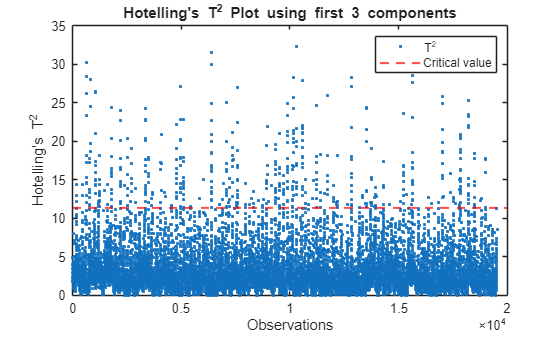

97.25 % of observations are below the Hotelling's T^2 limit.


% PCA Monitoring with Hotelling's T² and SPE (Q-statistic)

% Standartized clean data, 3 PCs, alpha 0.99
utils.T2chart(standardizedTableClean{:,:}, 3, 0.99)

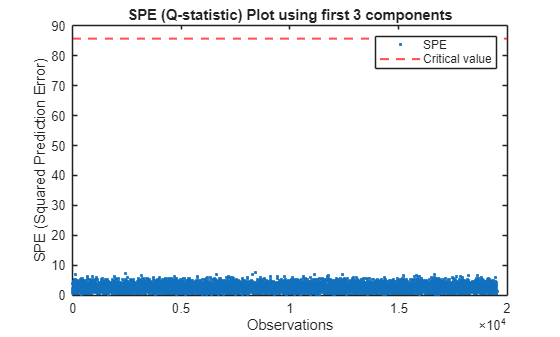

100.00 % of observations are below the SPE limit.


utils.SPEchart(standardizedTableClean{:,:}, 3, 0.99)

### Pretreated data distributions

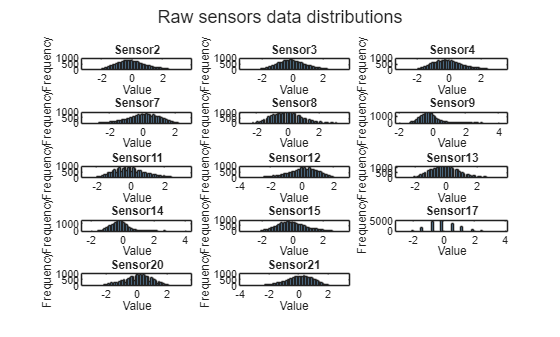

%% Extract sensor column names
% Get all variable names from the sensor table
sensorCols = standardizedTableClean.Properties.VariableNames;

% Number of sensors
nSensors = numel(sensorCols);

% Define subplot grid (3 columns)
cols = 3;
rows = ceil(nSensors / cols);

%% Plot histogram for each sensor
figure;
for i = 1:nSensors
    subplot(rows, cols, i)                            % create subplot
    histogram(standardizedTableClean.(sensorCols{i})) % plot histogram for current sensor
    xlabel('Value')                                   % x-axis label
    ylabel('Frequency')                               % y-axis label
    title(sensorCols{i})                              % individual subplot title
end

% Add a super title for the entire figure
sgtitle('Raw sensors data distributions')          